# Low Code App-based Workflow for the Biomedical Signals 

We will use the same generated data to perform the workflow 

## Create and visualize signals in MATLAB (Same as e11)

We will start out by creating one. 

% set the sampling rate of the signal as 1 KHz as varabile Fs
Fs = 1e3; 

% Duration of signal as 1 second
t = 0:1/Fs:1-1/Fs; 

% Tone at 200 Hz after 0.7 seconds (or select with drop down)
comp1 = cos(2*pi*100*t).*(t>0.7); 

% Tone at 60 Hz between 0.1 and 0.3 seconds
comp2 = cos(2*pi*60*t).*(t>0.1 & t<0.3);

% Low frequency trend at 0.5 Hz
trend = sin(2*pi*1*t); 
rng default; 

% Noise
wgnNoise = 0.4*randn(size(t)); 

% Signal with all parts combined
x = comp1 + comp2 + trend + wgnNoise; 


We can visualize the signal using plot. 

% Visualize
plot(t,x); 
xlabel("second"); 
ylabel("Amplitude");

## Analyze the signals in spectrum and time-frequency domains

When analyzing non-stationary signals in the spectrum (frequency domain) and time-frequency domain, a key point to remember is that a non-stationary signal's frequency content changes significantly over time, meaning a standard Fourier transform alone won't capture this dynamic behavior; therefore, time-frequency analysis techniques like the Short-Time Fourier Transform (STFT) or wavelet transform are crucial to visualize how the signal's frequencies evolve across time.

## Use **Signal Analyzer**

Now we have data x in the workspace. Open **Signal Analyzer** and drag the timetable from the **Workspace Browser** to the Signal table. Click **Display Grid** to create two side-by-side displays. Select each display and, in the **Display** tab, click **Time-Frequency** to add a spectrogram view.

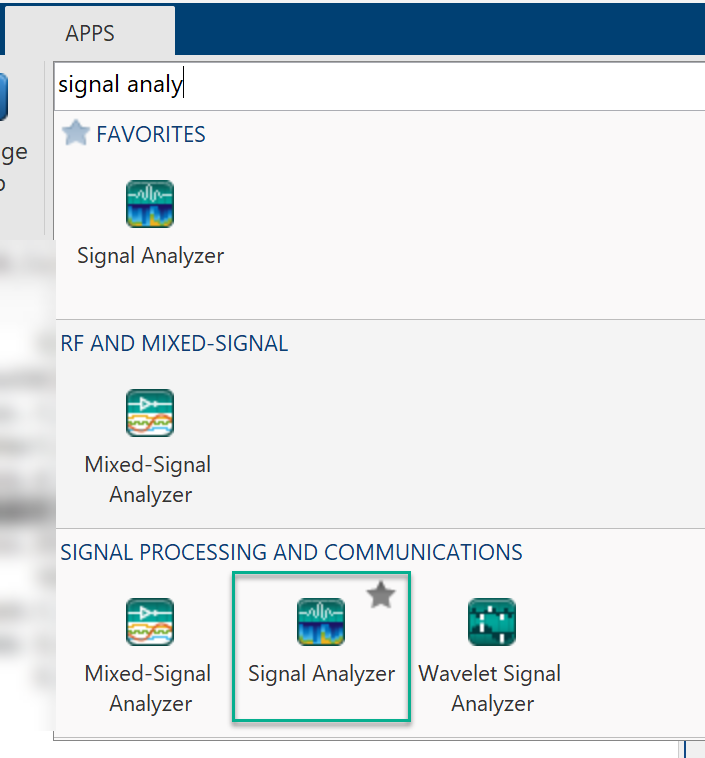

In the Signal Analyzer, you can drag and drop signals from your MATLAB workspace to view the signal. You can pan and focus on regions of interest. Look into the frequency spectrum of the signal. You can analyze the signal in the time-frequency domain with the spectrogram and scalogram. 

You can also export the script for the same analysis. 

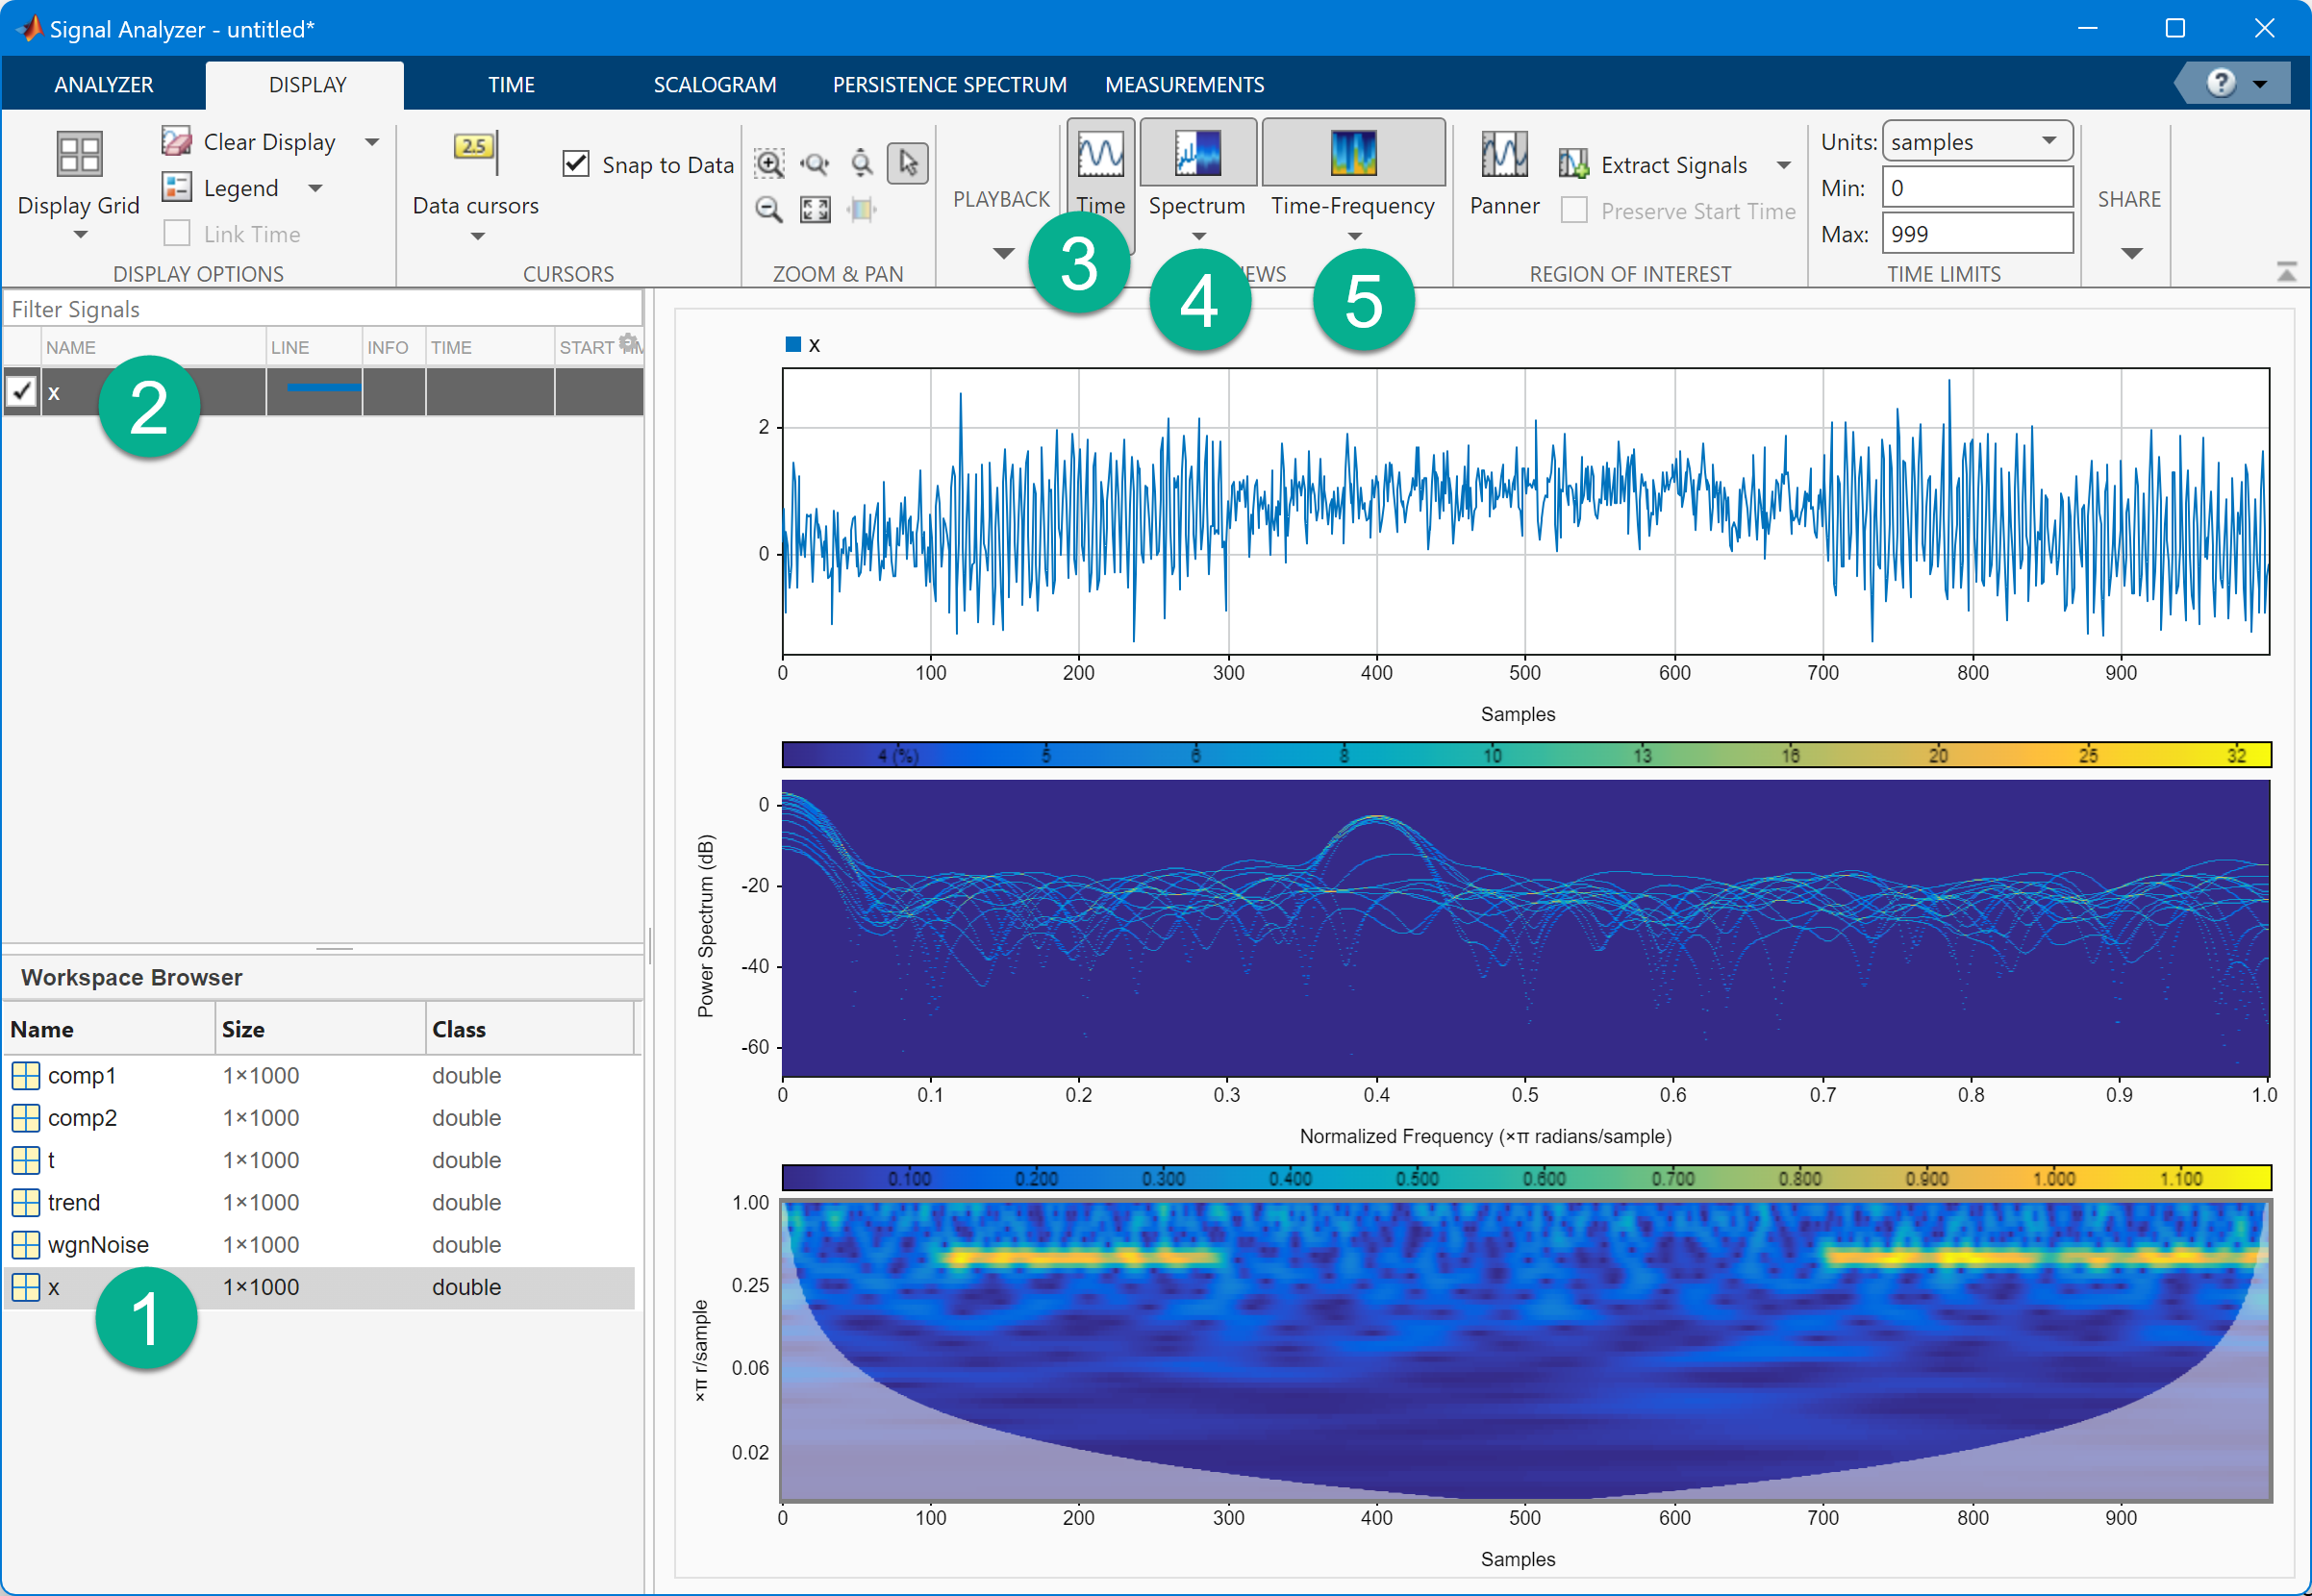

### Make use of a few other Apps for analysis

Using the variable x in the workspace, you can try these Apps to perform in depth analysis. 

- Signal Analyzer; 

- Signal Multiresolution Analyzer; 

- Wavelet Signal Analyzer; 

- Wavelet Signal Denoiser; 

- Wavelet Time Frequency Analyzer. 

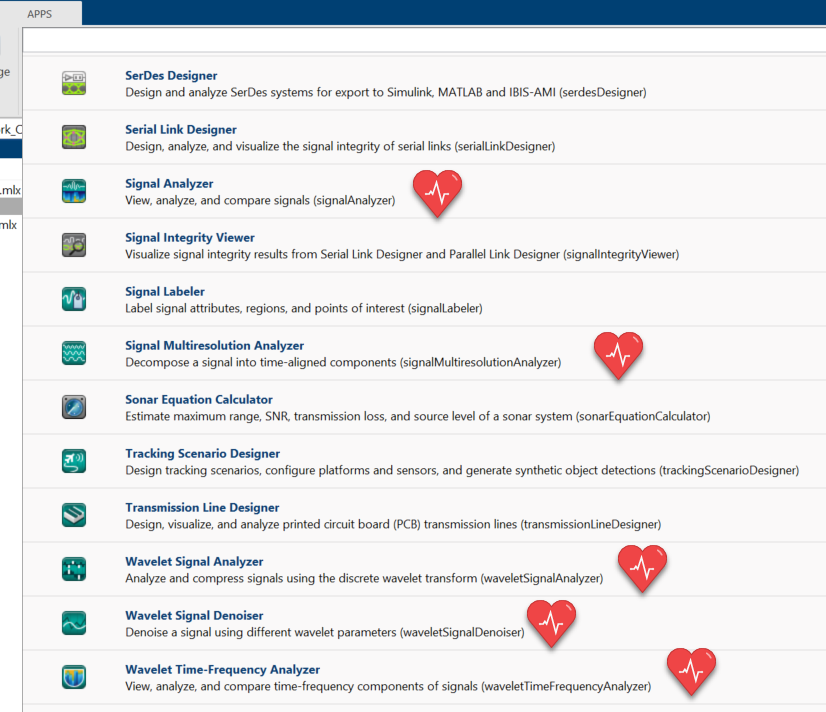

## Summary

Explored the workflow in DSP System Toolbox™ and Wavelet Toolbox™. 